%% Finding MX-ONMTF with modularity density for real networks.
% %for fixed number of common communities, and the number of private and total commmunities per layer.

%load("findK_eg2_d5_k6.mat", "kc","k","kp", "Z");

load("findK_eg21_d5_k6.mat", "kc","k","kp", "Z");

%load("fixed_k6_kc3_kpl3", "kc","k","kpl");

Al = importdata("theta_theta_all.mat");

load("notFixed_eg2_d5_k6.mat", "ClustersSupra");

topo_plots = '10-5-System_Mastoids_EGI129.locs';


kpl=kp;
ClustersSupra = ClustersSupra; %length(unique(ClustersSupra))
k=k;

un_len = max(ClustersSupra);

colors = random_color(un_len);

L = 20; %20 layers
x=1;
z=64;
y=1;


figure(1)
A = Al{1};
B = triu(A,1); % Extract the upper triangular part of the matrix
data = reshape(B, [], 1); % Reshape the matrix into a vector

clusterssupra_total = []


clusterssupra_total =

     []



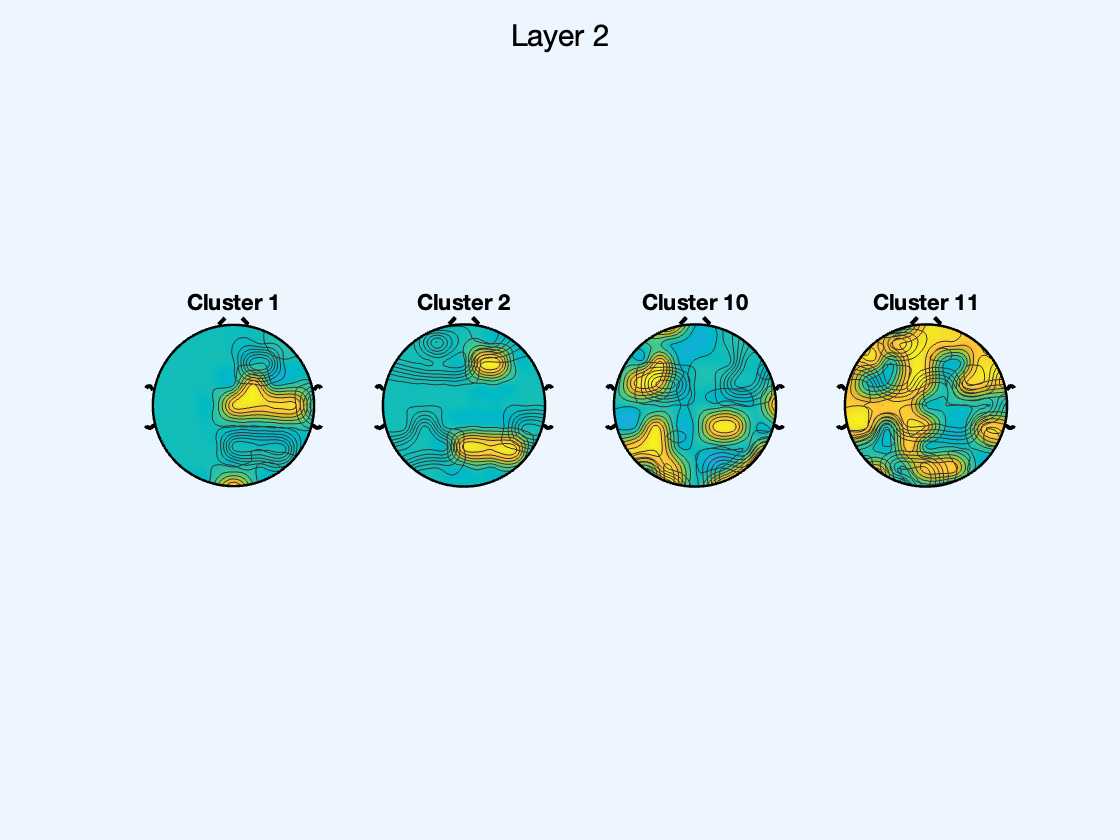

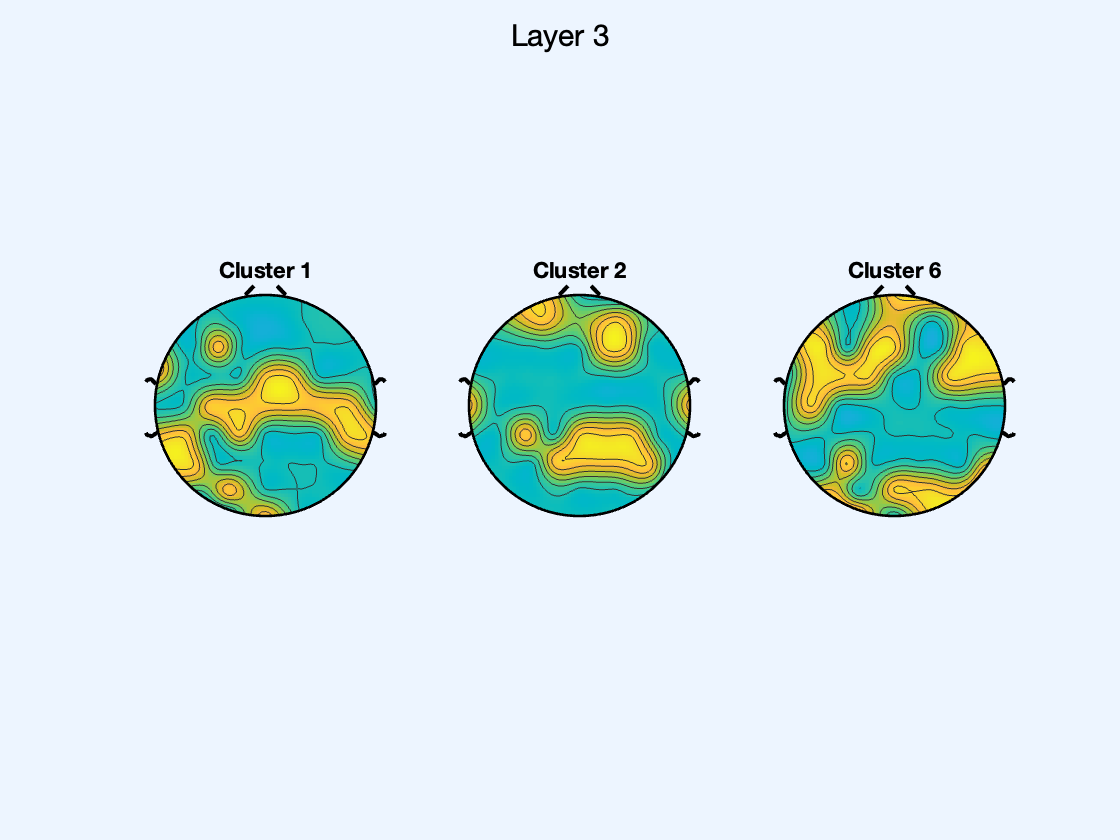

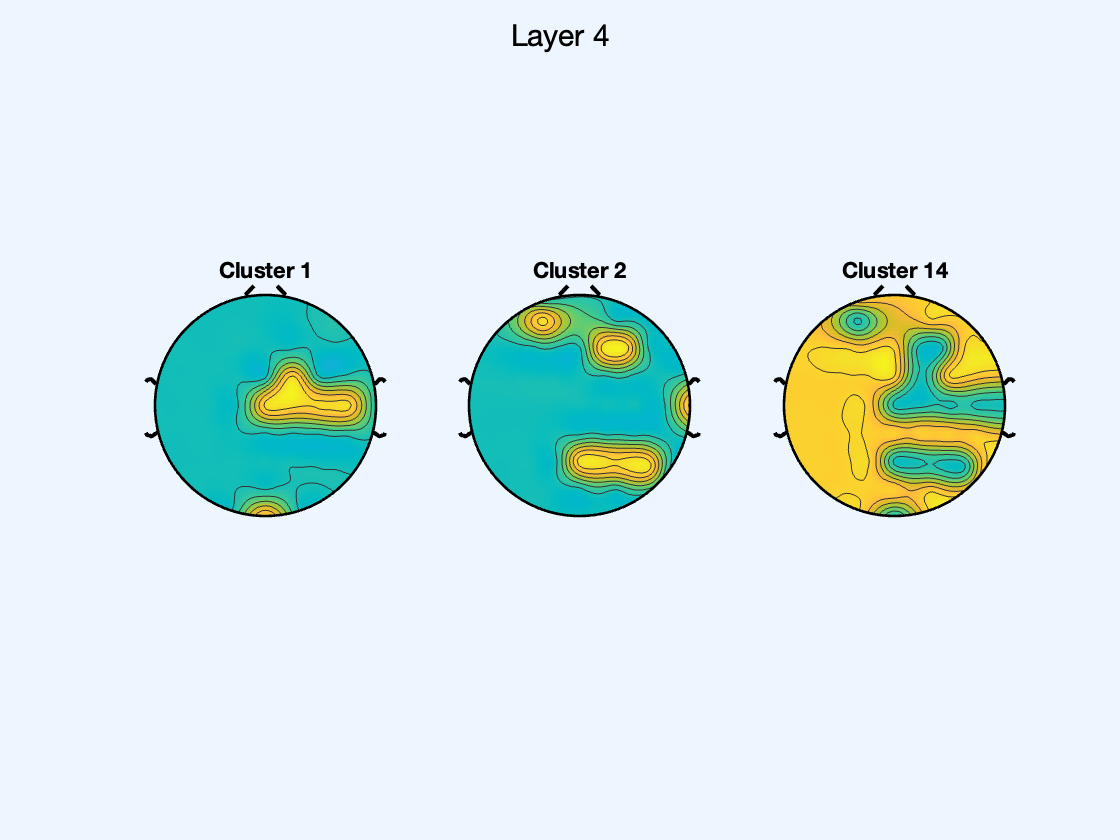

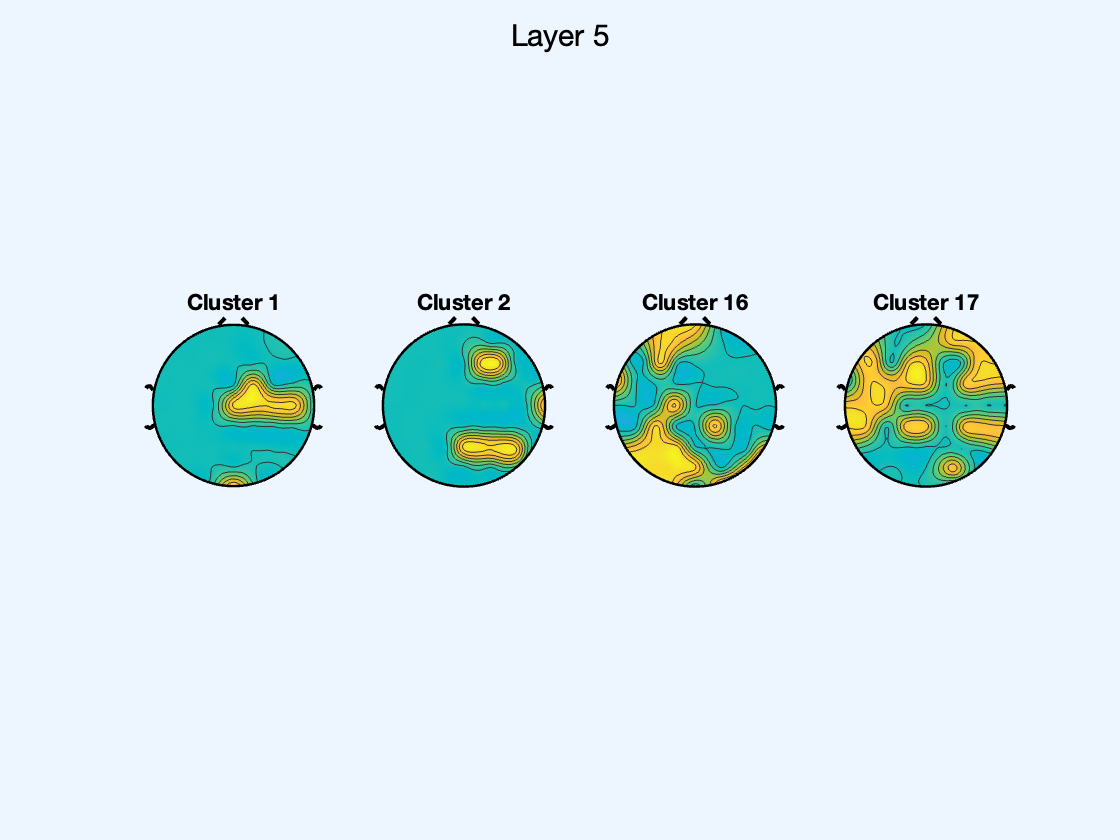

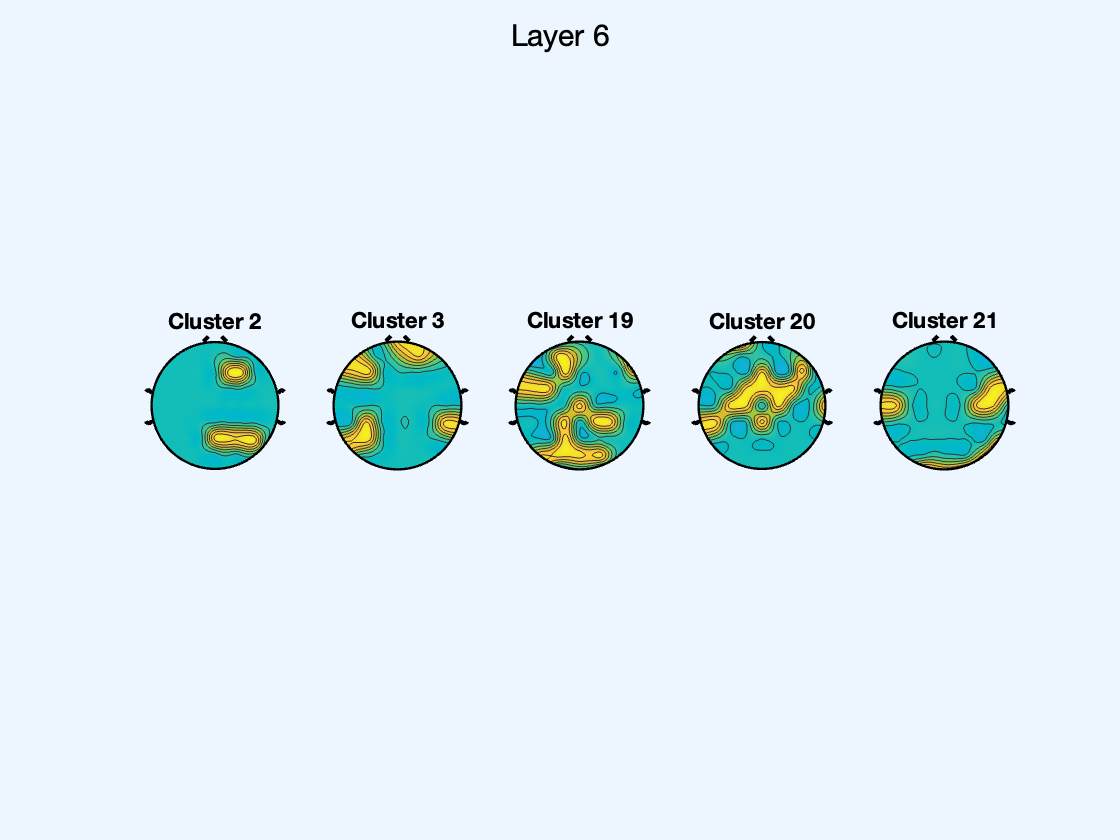

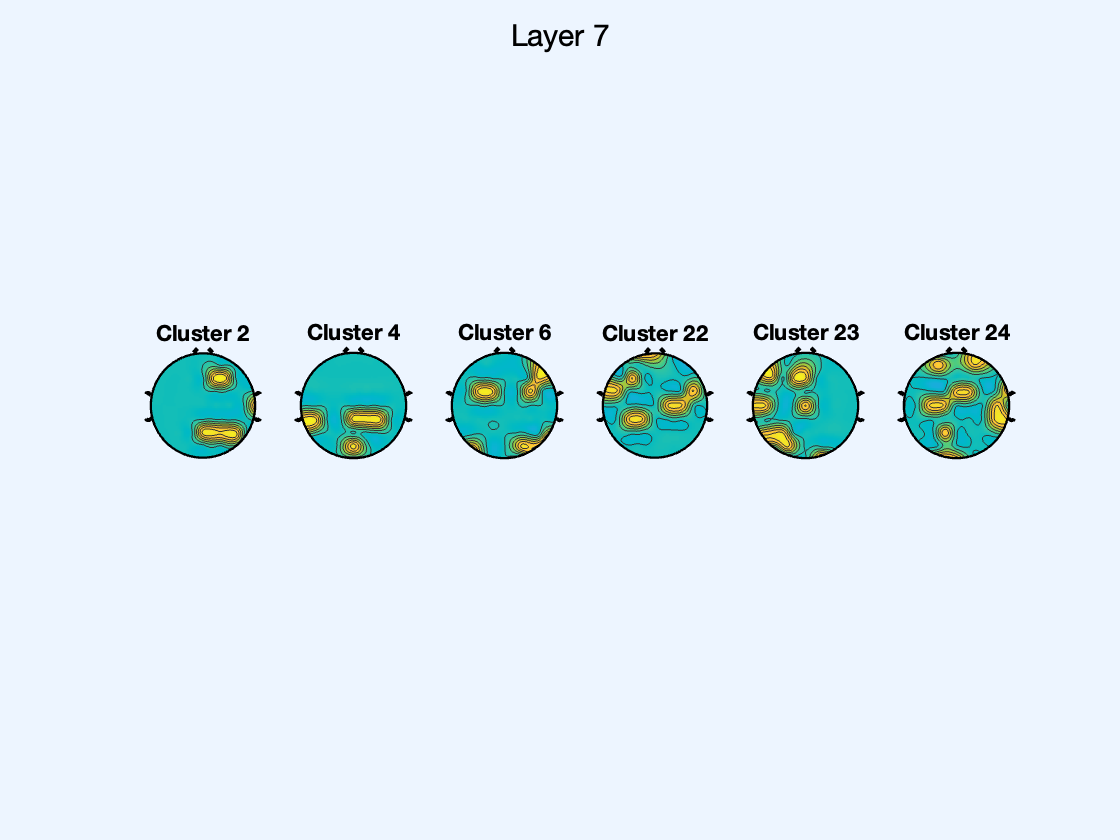

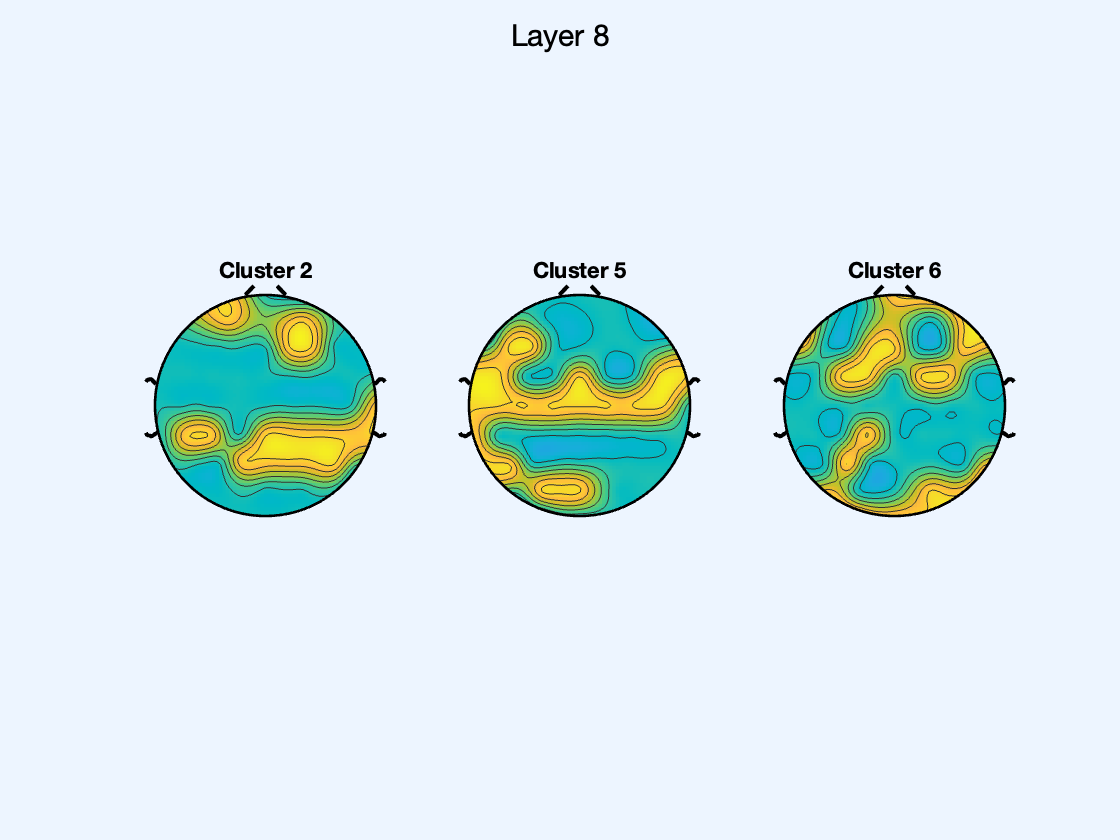

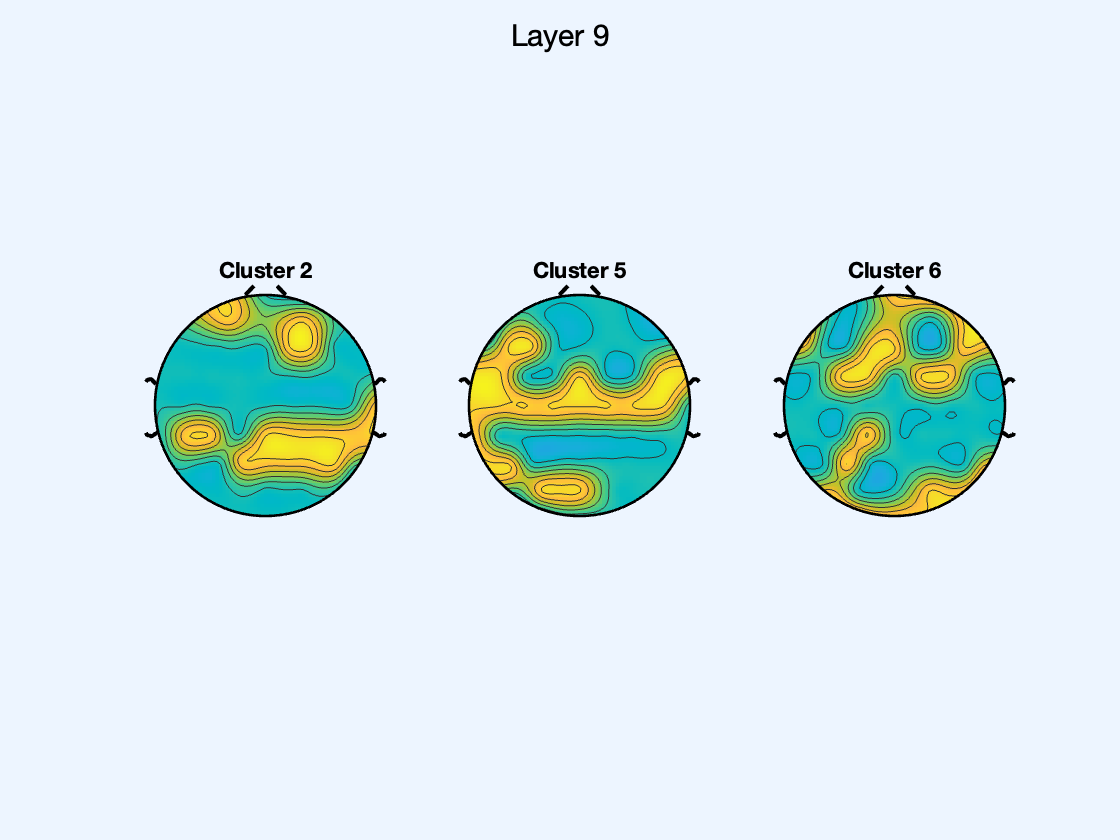

%figure(2)
for cindex=1:L
    
    A = Al{cindex};
    B = triu(A,1); % Extract the upper triangular part of the matrix
    data = reshape(B, [], 1); % Reshape the matrix into a vector
    
    %subplot(4,5,cindex);
    figure(cindex)
    sgtitle(sprintf('Layer %d', cindex));
    
    % Original code
    topoplot(data, topo_plots, 'style', 'both'); %, 'electrodes', 'on');
   
    k_labels = unique(ClustersSupra(x:z));
    clusterssupra_total = [clusterssupra_total, {k_labels}];
   
    LegendsStrings = cell(length(k_labels),1); % Initialize array  with legends
    highlight_nodes = {}; % Indices of nodes to highlight
    highlight_colors = []; % Colors of the highlighted nodes in RGB format
    
    for index=1:length(k_labels)
        label = k_labels(index);
        new_color = colors(label,:);
        new_nodes = find(ClustersSupra(x:z) == label)'; % Indices of nodes to highlight
        
        highlight_nodes = [highlight_nodes, {new_nodes}];
        highlight_colors = [highlight_colors; new_color];
        
    end

   
    for i = 1:length(highlight_nodes)
        highlight = highlight_nodes{i};
        
        %
        %data_highlight = data;
        %data_highlight(highlight) = data_highlight(highlight) + 10; % Increase data values for highlighted nodes
        %topoplot(data, topo_plots, 'style', 'both'); % Plot original data
        
        
        %data_highlight = zeros(size(data));
        %data_highlight(highlight) = data(highlight);
        
        data_highlight = data;
        data_highlight(highlight) = data_highlight(highlight) + 10; % Increase data values for highlighted nodes
        
        %colormap(highlight_colors);
        %hold on
        hold on
        %highlight_colors(i,:)
        subplot(1,length(k_labels),i);
        title(sprintf('Cluster %d', k_labels(i)));
        %highlight_colors(i,:)
        topoplot(data_highlight, topo_plots, 'style', 'both');% 'colormap',[1 0 0]);
        %topoplot(data_highlight, topo_plots, 'style', 'map', 'plotchans', plotchans3d, 'colormap', highlight_colors(i,:));
    end
    
    %break
    
    x=x+64;
    z=(x+63);
    hold off

end